optimParams_v1

Optim Params by using Surrogate optimization for an expensive optimization problems

Define upper, lower bound and constraints

startTime = tic
% Define upper, lower and bound 
 

startTime = uint64
2071537543493

% optimPoint = 10
% lookbackUB = nsteptrain-optimPoint;
% counter help  = [1    2           3   4           5           6   7   8           9   10          11]
% lb              = [20   1           5   1           1           2   80  10          1   1           0] ;
% ub              = [150  lookbackUB  60  lookbackUB  lookbackUB  30  250 lookbackUB  10  lookbackUB  15] ;
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
lb              = [60   50  5   1   2   0   60  5   3   1   0 ] ;
ub              = [250  200 60  10 10   15  250 30  5   5   8 ] ;

% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 


% Integer constraints
nvars = 11 ;
intcon = 1:nvars ;

% Objective & constraints function
% dataInput = load("pricevolumedata.mat") ;

% f =  @(x)objconstrFcn(x, dataInput, optimPoint);

optimPoint = 5

% f =  @(x)objFcn(x, dataInput, optimPoint);
obj = @(x)objFcn(x, dataInput, optimPoint) ;
nlconst = @(x)nlconstFcn(x, dataInput, optimPoint) ;

objconstr = packfcn(obj,nlconst) ;
f = objconstr ;

% Set options
maxFcnEval = 300;
opts = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-4, "MaxFunctionEvaluations",maxFcnEval, ...
    "UseParallel", true, "UseVectorized",true);


Call `surrogateopt` to solve the problem

Objective or constraint function returned NaN.


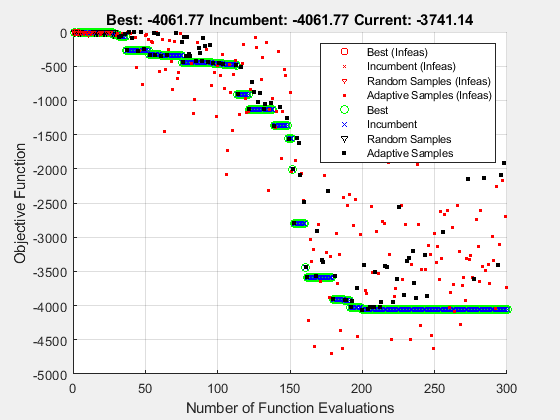

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    122    62    10     1    17     2   132    47     4     5     5


fval = -4.0618e+03

exitflag = 0

outpt = struct with fields:
        elapsedtime: 434.3449
          funccount: 300
    constrviolation: -0.0015
               ineq: [-0.0015 -3.8381]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 434.9087

paramsInput =    122    62    10     1    17     2   132    47     4     5     5


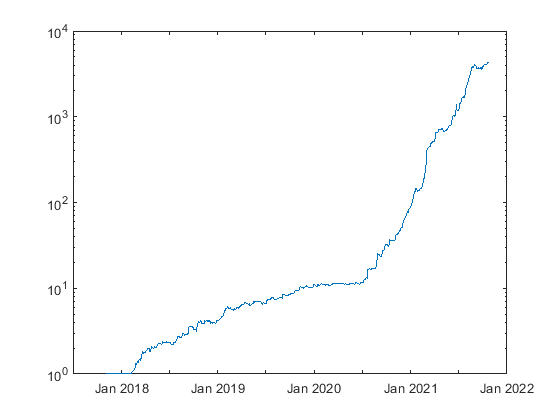

portEndValue = 4.2125e+03

portMinValue = 1

portMaxValue = 4.3009e+03

MaxDD = 0.1485

MaxDDIndex =    231
   245


drawdownDate = 2×1 datetime array
   2018-09-21
   2018-10-11


sharpeRatio = 4.8381

FortValueAtOptPoint = 4.0618e+03

PortRetOptPtEnd = 0.0371

optimPointDate = datetime
   2021-10-14


nYear = 3.9699

CAGR = 7.1849

dailyRetAvg = 0.0088

dailyRetMin = -0.1379

dailyRetMax = 0.2734

symRank = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'BNBA'}       {[1.3339]}    
    {'ACST'}       {[1.3303]}    
    {'ABBA'}       {[1.2428]}    
    {'BBHI'}       {[1.2369]}    
    {'SURE'}       {[1.2349]}    
    {'FIRE'}       {[1.2278]}    
    {'ZBRA'}       {[1.2235]}    
    {'DMMX'}       {[1.2170]}    
    {'TCPI'}       {[1.2119]}    
    {'BRIS'}       {[1.2113]}    
    {'BINA'}       {[1.2003]}    
    {'BBYB'}       {[1.1954]}    
    {'REAL'}       {[1.1778]}    
    {'MLPL'}       {[1.1744]}    
    {'FILM'}       {[1.1740]}    
    {'BOLA'}       {[1.1690]}    


stockPick = 6×2 table
     symbol     TradingSignal
    ________    _____________

    {'BBHI'}        {[1]}    
    {'MAPA'}        {[1]}    
    {'PANR'}        {[1]}    
    {'SGER'}        {[1]}    
    {'SRTG'}        {[1]}    
    {'SSMS'}        {[1]}    


counterhelp =      1     2     3     4     5     6     7     8     9    10    11


sol =    122    62    10     1    17     2   132    47     4     5     5


lb =     20    50     5     1     3     2    80    10     1     1     0


ub =    150   150    60     6    20    30   250    60    10     8    15


% Call surrogateopt to solve the problem
% rng default % For reproducibility
[sol,fval,exitflag,outpt] = surrogateopt(f,lb,ub,intcon,opts)

endTime = toc(startTime)
